# **Repetition Rate Analysis**

### For species with a single note type

load('sample_dataset_prinia_project.mat')

%get intersyllable intervals from acoustic data
BT_j = BT(ismember(SC,'S')&ismember(P,'J'));
ET_j = ET(ismember(SC,'S')&ismember(P,'J'));
is_int_j = BT_j(2:end)-ET_j(1:end-1);
is_int_j(is_int_j<0) = [];
is_int_j(is_int_j>0.3) = [];

BT_p = BT(ismember(SC,'S')&ismember(P,'P'));
ET_p = ET(ismember(SC,'S')&ismember(P,'P'));
is_int_p = BT_p(2:end)-ET_p(1:end-1);
is_int_p(is_int_p<0) = [];
is_int_p(is_int_p>0.3) = [];

%>0.3 millisecond is indicative of file change and all those values are
%ignored

**Distribution of Intersyllable Intervals (ISI)**

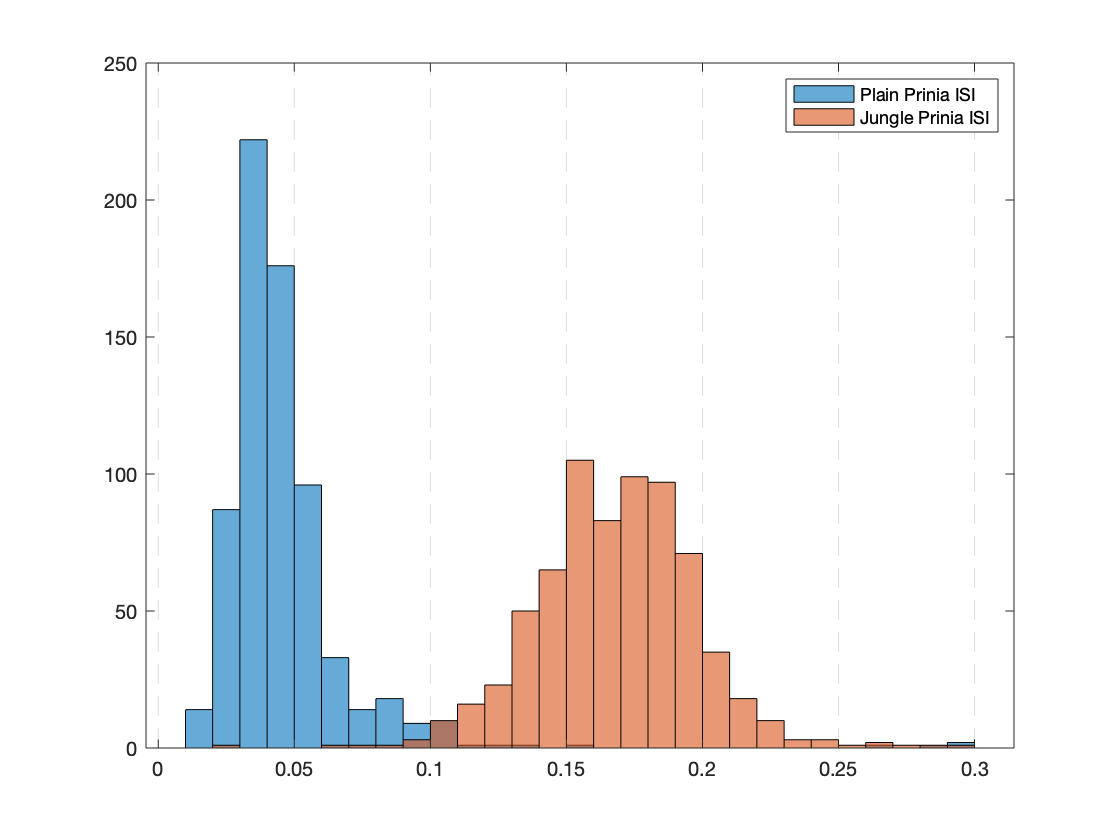

clf;
histogram(is_int_p); hold on;
histogram(is_int_j);
legend('Plain Prinia ISI','Jungle Prinia ISI')
ax = gca;
ax.XGrid = 'on';
ax.GridLineStyle = '--';

**Probability Density Functions**

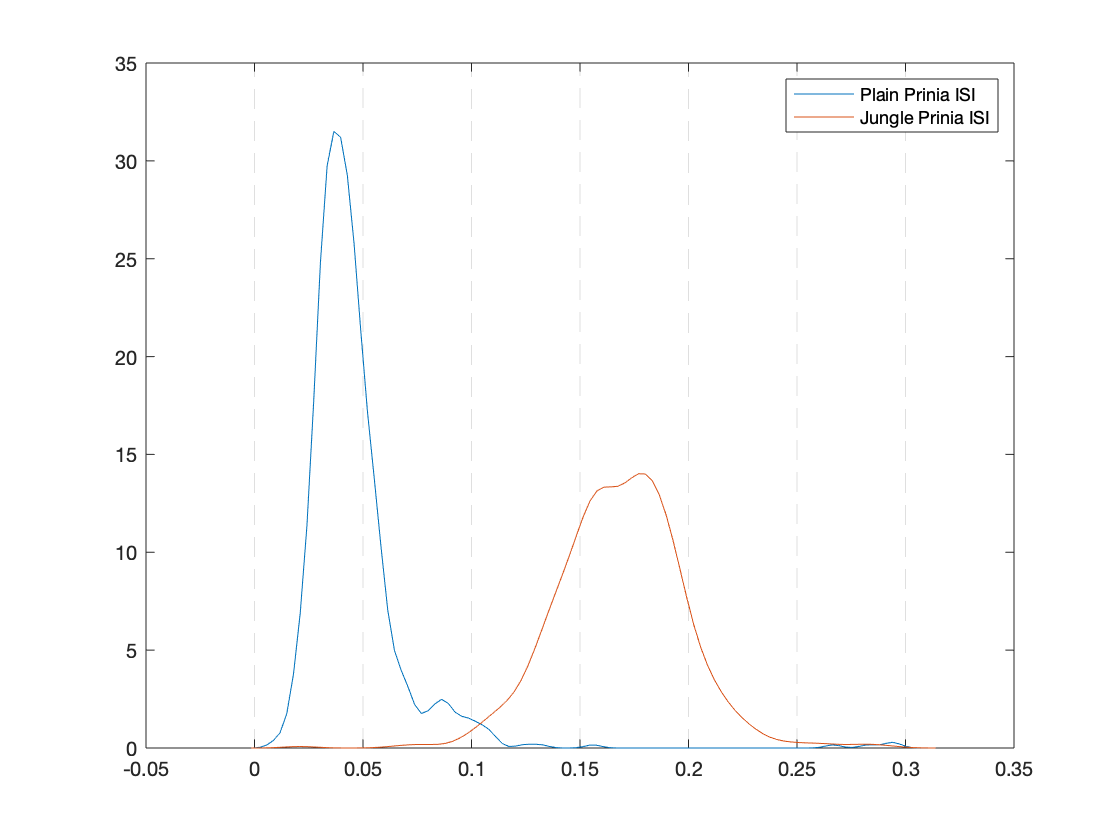

clf;
ksdensity(is_int_p); hold on;
ksdensity(is_int_j);
legend('Plain Prinia ISI','Jungle Prinia ISI')
ax = gca;
ax.XGrid = 'on';
ax.GridLineStyle = '--';